# Milestone 2 Crop ROI from Imahe

Requirements:

1) Image Processing Toolbox

### Open Image Segmentation Tool

- you may skip this part, I have generated the function from this tool and place the function at the end of this script.

imageSegmenter

To Mask the road out from image :

1) Load Any Image from folder dataset/2701

2) Draw ROI - Polygon

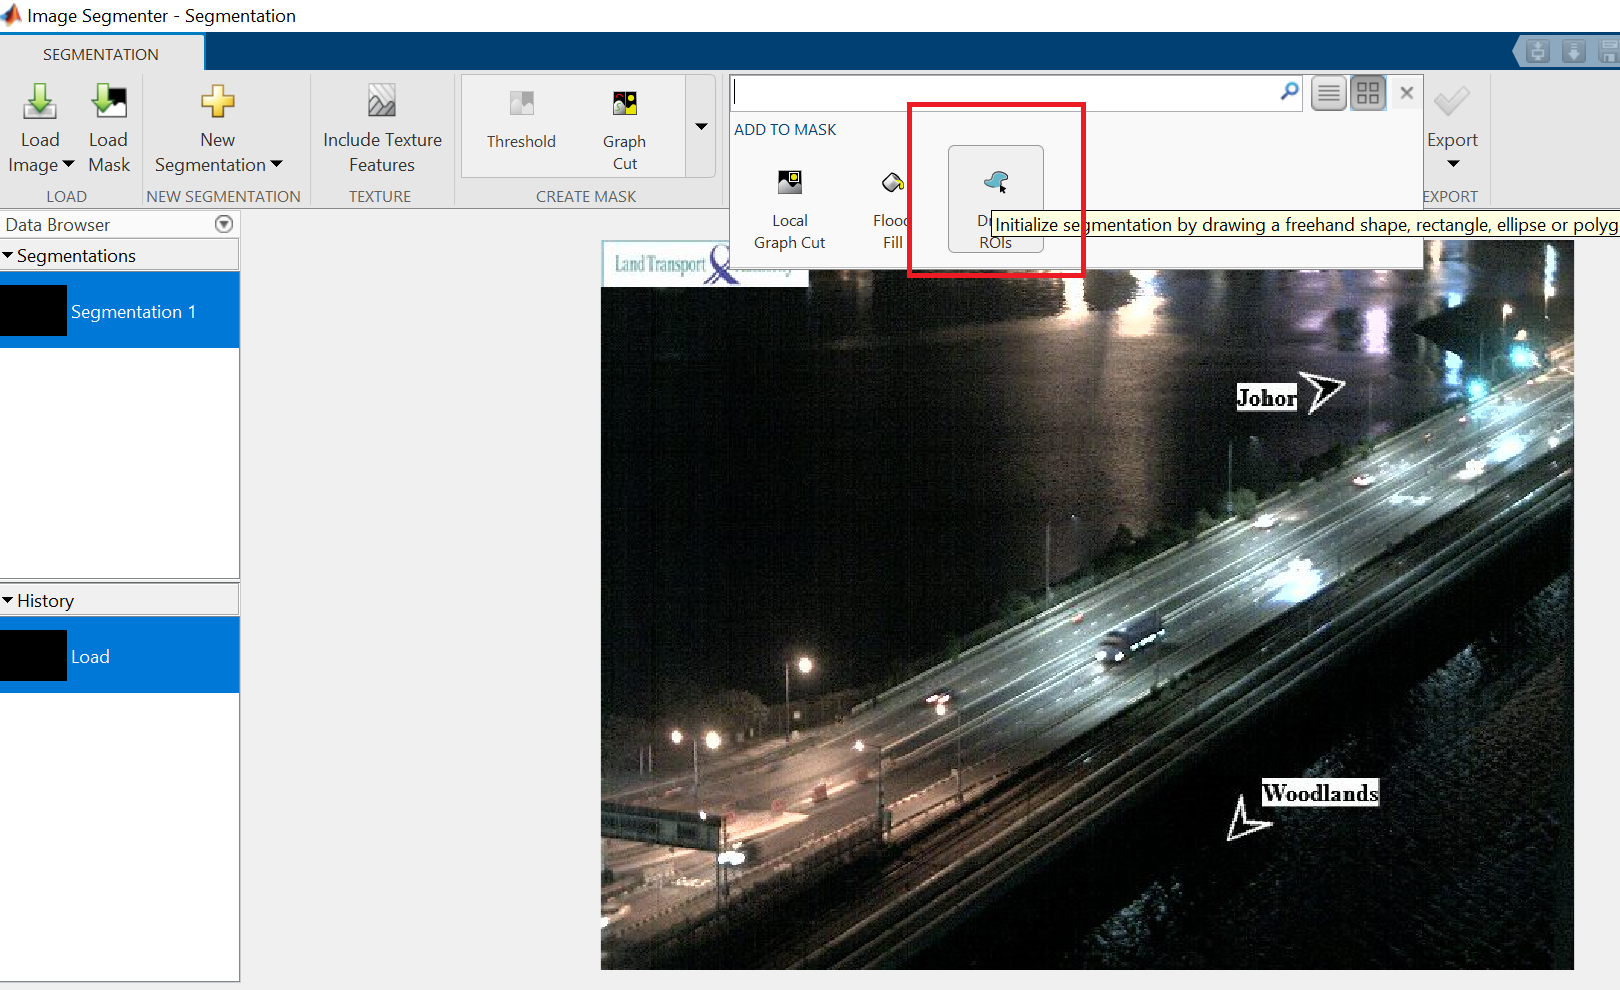

3) Once completed, generate function as segmentImage_2701.m

Repeat for Image from 2702, generate function as segmentImage_2702.m

### Select camera id to Visualize the image and location

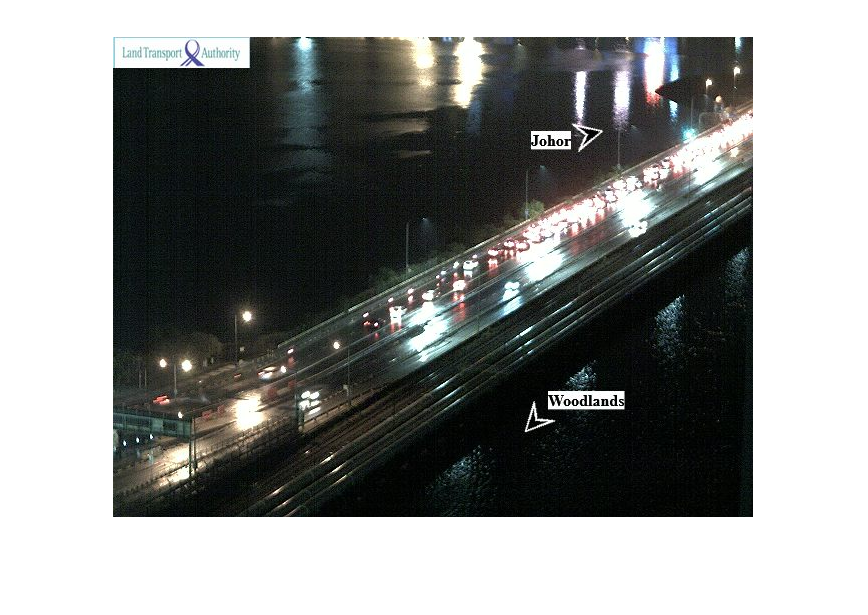

id = "2701";
w1=strcmp(string(cell2mat(w(:,4))),id);
imshow(imread(r.items.cameras(w1).image))

wmmarker(r.items.cameras(w1).location.latitude,r.items.cameras(w1).location.longitude);

### Crop All the Images from folder dataset/2701 and folder dataset/2702

try
     mkdir dataset/2701_ROI
     mkdir dataset/2702_ROI
catch ME
     fprintf("Folders(2701_ROI & 2702_ROI) are available")
end

cd('dataset/2701')
W_2701=dir("*.png");
cd("..")
cd("..")
cd('dataset/2702')
W_2702=dir("*.png");
cd("..")
cd("..")

%for 2701
for i=1:1:length(W_2701)
    W=imread([W_2701(i).folder '\' W_2701(i).name]);
    [~,maskedImage] = segmentImage2701(W);
    imwrite(maskedImage,['dataset\2701_ROI\' W_2701(i).name]);
end

%for 2702
for i=1:1:length(W_2702)
    W=imread([W_2702(i).folder '\' W_2702(i).name]);
    [~,maskedImage] = segmentImage2702(W);
    imwrite(maskedImage,['dataset\2702_ROI\' W_2702(i).name]);
end

### Supporting Function

function [BW,maskedImage] = segmentImage2701(RGB)
%segmentImage Segment image using auto-generated code from imageSegmenter app
%  [BW,MASKEDIMAGE] = segmentImage(RGB) segments image RGB using
%  auto-generated code from the imageSegmenter app. The final segmentation
%  is returned in BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 28-Sep-2020
%----------------------------------------------------


% Convert RGB image into L*a*b* color space.
X = rgb2lab(RGB);

% Create empty mask.
BW = false(size(X,1),size(X,2));

% Draw ROIs

xPos = [0.5000 66.6918 160.7192 407.2945 639.4041 640.5000 142.9658 0.5000];
yPos = [362.4726 344.7192 311.8425 181.6507 63.9521 167.8425 480.5000 480.5000];
m = size(BW, 1);
n = size(BW, 2);
addedRegion = poly2mask(xPos, yPos, m, n);
BW = BW | addedRegion;

% Create masked image.
maskedImage = RGB;
maskedImage(repmat(~BW,[1 1 3])) = 365; % I change it to 365, because i want mask to white
end

function [BW,maskedImage] = segmentImage2702(RGB)
%segmentImage Segment image using auto-generated code from imageSegmenter app
%  [BW,MASKEDIMAGE] = segmentImage(RGB) segments image RGB using
%  auto-generated code from the imageSegmenter app. The final segmentation
%  is returned in BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 28-Sep-2020
%----------------------------------------------------


% Convert RGB image into L*a*b* color space.
X = rgb2lab(RGB);

% Create empty mask.
BW = false(size(X,1),size(X,2));

% Draw ROIs

xPos = [86.3537 109.7683 122.1643 185.5215 227.5301 282.6234 318.4340 381.7912 444.4598 520.9017 640.5000 635.9089 516.0811 392.1212 436.1958 372.1499 318.4340 225.4641 220.6435 367.3293 456.8558 640.5000 640.5000 507.1284 387.9892 180.7009 147.6449];
yPos = [0.5000 97.9462 137.2001 163.3694 232.9247 262.5373 272.8673 307.9892 374.1011 478.7783 478.7783 441.5904 330.7152 266.6693 252.8960 233.6133 239.1227 163.3694 153.0395 166.1241 192.9821 361.7052 290.0839 184.7181 153.7281 126.1815 0.5000];
m = size(BW, 1);
n = size(BW, 2);
addedRegion = poly2mask(xPos, yPos, m, n);
BW = BW | addedRegion;

% Create masked image.
maskedImage = RGB;
maskedImage(repmat(~BW,[1 1 3])) = 365;% I change it to 365, because i want mask to white
end